# Simulation of simple random sampling and sampling distribution

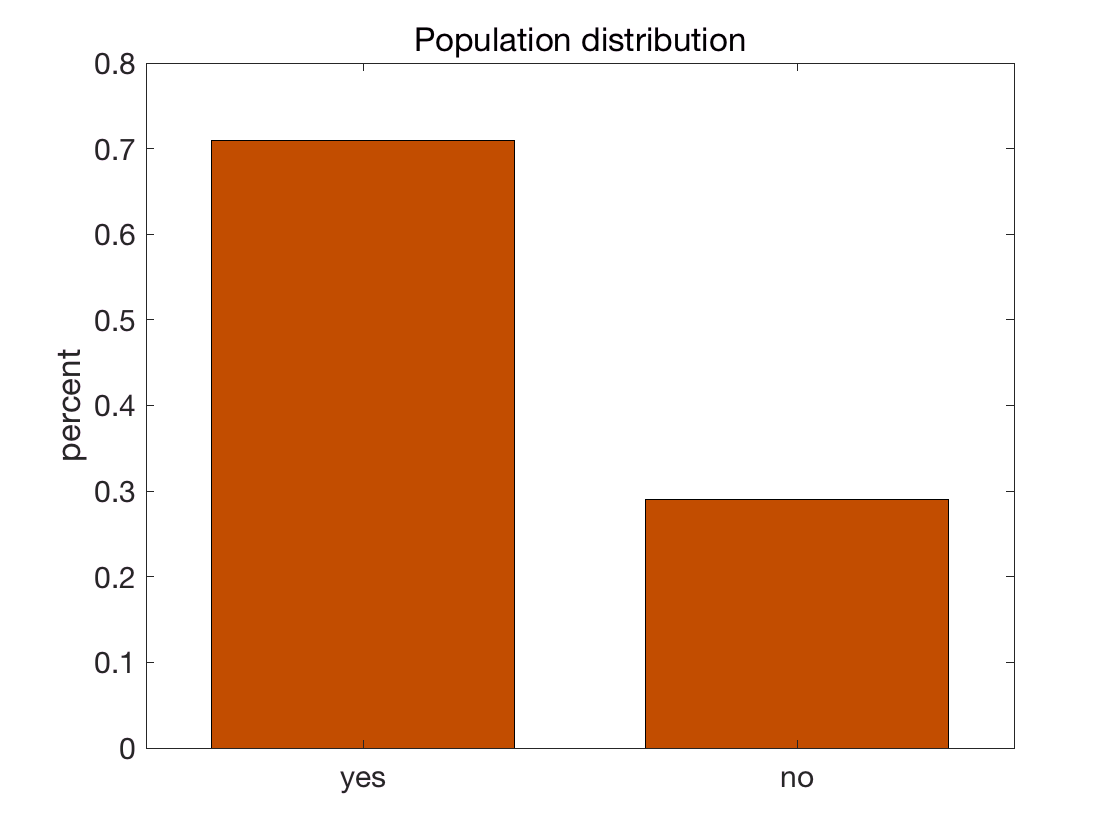

p = 0.71; % This is a parameter for the real approval rating. 
          % This value is unknown in reality, but let's assume that I'm God, and so I know it. 

population = zeros(51250000,1); % Korean population 51.2M
population(1:round(51250000*p)) = 1; % People who approve the current president

% Simple random sampling
iter = 1000;
sample_n = linspace(20, 800, 6);
for i = 1:numel(sample_n)
    for j = 1:iter % let's say we did the survey 1000 times
        sample = population(randperm(numel(population), sample_n(i))); % simple random sampling
        p_sample{i}(j) = sum(sample==1)/numel(sample); % get the sample statistics for the approval rating
    end
end

% population distribution
figure;
bar([.71, 1-.71], .7, 'facecolor', [0.7608 0.3020 0]);
set(gca,'XTickLabel', {'yes', 'no'}, 'fontsize', 15)
title('Population distribution')
ylabel('percent');

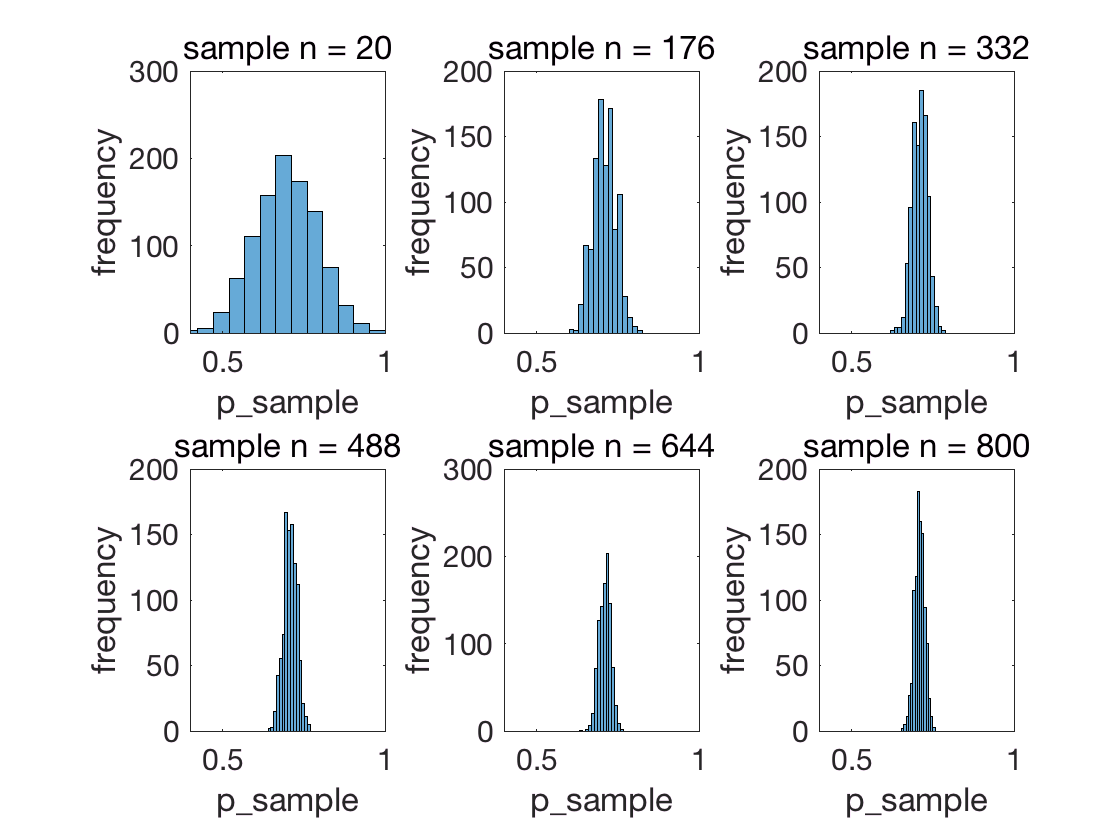


For sample n = 20, Mean = 0.71, Standard deviation = 0.1015, SD from a normal model = 0.1015


For sample n = 176, Mean = 0.71, Standard deviation = 0.0346, SD from a normal model = 0.0342


For sample n = 332, Mean = 0.71, Standard deviation = 0.0238, SD from a normal model = 0.0249


For sample n = 488, Mean = 0.71, Standard deviation = 0.0206, SD from a normal model = 0.0205


For sample n = 644, Mean = 0.71, Standard deviation = 0.0181, SD from a normal model = 0.0179


For sample n = 800, Mean = 0.71, Standard deviation = 0.0158, SD from a normal model = 0.0160




% sampling distribution
figure;
for i = 1:numel(sample_n)
    subplot(2,3,i)
    histogram(p_sample{i}, 15);
    set(gca, 'fontsize', 15, 'xlim', [0.4 1]);
    title(['sample n = ' num2str(sample_n(i))]);
    xlabel('p\_sample');
    ylabel('frequency');
    
    fprintf('\nFor sample n = %d, Mean = %2.2f, Standard deviation = %2.4f, SD from a normal model = %2.4f', sample_n(i), mean(p_sample{i}), std(p_sample{i}), sqrt(p*(1-p)/sample_n(i)));
end